TIME_OFFSET = 0.9;
ERROR_WITH_ROLLER_MEASURMENT = 0.0005;
ERROR_FOR_CAPSTONE_MEASUREMENTS = 0.01;

one_mass_raw_data = readtable('one_mass.csv'); 

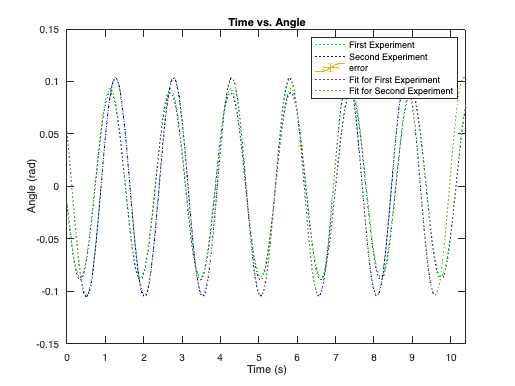

time_vals_for_run_one = one_mass_raw_data.time1;
angle_vals_for_run_one = one_mass_raw_data.angle1 - mean(one_mass_raw_data.angle1, "omitmissing");
plot(time_vals_for_run_one, angle_vals_for_run_one,':', "Color", "green")
hold on 
time_vals_for_run_two = one_mass_raw_data.time2 - TIME_OFFSET;
angle_vals_for_run_two = one_mass_raw_data.angle2 - mean(one_mass_raw_data.angle2, "omitmissing");
plot(time_vals_for_run_two, angle_vals_for_run_two,':', "Color", "blue")
% hold on
errorbar(time_vals_for_run_two(700:700,1:1), angle_vals_for_run_two(700:700,1:1), 0.0001, 0.0001, 0.0001, 0.0001);
% cftool(time_vals_for_run_one, angle_vals_for_run_one, [], standard_error_first_run)
% cftool(time_vals_for_run_two, angle_vals_for_run_two, [], standard_error_second_run)
plot(fit_for_run_one,':')
plot(fit_for_run_two,':')

legend('First Experiment', 'Second Experiment', "error", 'Fit for First Experiment',...
    'Fit for Second Experiment')

xlabel("Time (s)")
ylabel("Angle (rad)")
xlim([0, max(time_vals_for_run_one)])
title("Time vs. Angle")
hold off

hold off
one_mass = readtable('lab_2_mesurments_one_mass.xlsx'); 
two_masses= readtable('lab_2_mesurments_two_masses.xlsx'); 
two_masses.actual_height_from_top = two_masses.Var4;
two_masses.omega_from_capstone = two_masses.Var5;
hold off

% One Mass
scatter(one_mass.actual_height_from_top, one_mass.omega_from_capstone, "Color", "green", 'DisplayName','one mass')
hold on
errorbar(one_mass.actual_height_from_top, one_mass.omega_from_capstone, ERROR_WITH_ROLLER_MEASURMENT , ERROR_WITH_ROLLER_MEASURMENT, ERROR_FOR_CAPSTONE_MEASUREMENTS, ERROR_FOR_CAPSTONE_MEASUREMENTS, "Color", "green", 'DisplayName','one mass - error', 'HandleVisibility','off');
hold on 
% Two Masses
scatter(two_masses.Var4, two_masses.Var5, "Color", "blue", 'DisplayName','two masses')
hold on
errorbar(two_masses.Var4, two_masses.Var5, ERROR_WITH_ROLLER_MEASURMENT , ERROR_WITH_ROLLER_MEASURMENT, ERROR_FOR_CAPSTONE_MEASUREMENTS, ERROR_FOR_CAPSTONE_MEASUREMENTS, "Color", "blue", 'DisplayName','two masses - error', 'HandleVisibility','off');
hold on
% Fit
fitted_function = @(x) (9.81/(x+0.07))^0.5;
fitted_function_2 = @(x) (9.81/(x+0.05))^0.5;
% cftool(two_masses.Var4, two_masses.Var5, [], ones(1, length(two_masses.Var5)) * ERROR_FOR_CAPSTONE_MEASUREMENTS)
fplot(fitted_function, [min(one_mass.actual_height_from_top), max(one_mass.actual_height_from_top)],'--', "Color", [0.9290, 0.6940, 0.1250], 'DisplayName','fit')

fplot(fitted_function_2, [min(two_masses.actual_height_from_top), max(two_masses.actual_height_from_top)],'--', "Color", [0.9290, 0.2940, 0.150], 'DisplayName','fit')

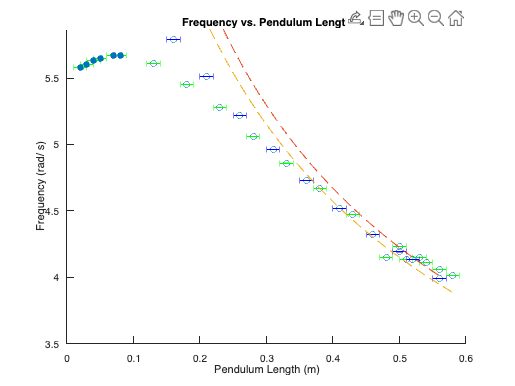

hold on
% Excluded Points
excluded_vals_in_one_mass = filter_data_by_x_vals(one_mass, 0.1);
excluded_vals_in_two_masses = filter_data_by_x_vals(two_masses, 0.1);
hold on
scatter(excluded_vals_in_two_masses.actual_height_from_top, excluded_vals_in_two_masses.omega_from_capstone, "filled", "Color", "red", 'DisplayName','one mass - excluded values for fit')
hold on
scatter(excluded_vals_in_one_mass.actual_height_from_top, excluded_vals_in_one_mass.omega_from_capstone, "filled", "Color", "red", 'DisplayName','two masses - excluded values for fit')


hold off
% legend
ylim([3.5, max(one_mass.omega_from_capstone + 0.2)])
title("Frequency vs. Pendulum Length")
xlabel("Pendulum Length (m)")
ylabel("Frequency (rad/ s)")

function error = get_std(y_vals)
    error = ones(1, length(y_vals)) .* ...
        std(y_vals - mean(y_vals, "omitmissing"), "omitmissing") ...
        ./ sqrt(length(y_vals));
end

function filltered_data = filter_data_by_x_vals(table, min_val)
    filltered_data = table(table.actual_height_from_top < min_val, :);
end








